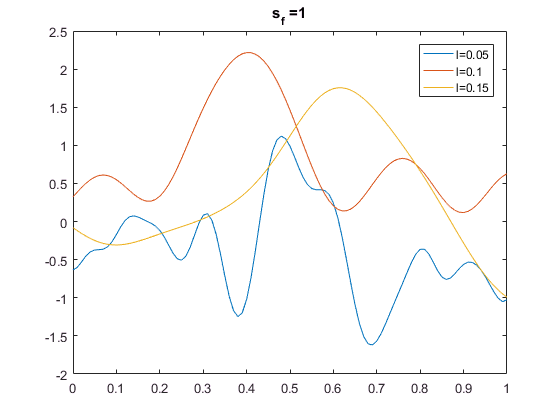

clear
clc
rng(123)

x = 0:0.01:1; x=x';
covfunc = @covSEiso;

figure(1)
ell1 = zeros(3,1);
for i = 1:3
    ell1(i) = 0.05* i;
    sf = 1;
    
    hyp_cov = log([ell1(i),sf]);
    gp_sample = gptp_sample(covfunc,x,hyp_cov);
    plot(x, gp_sample)
    hold on
end
legend(['l=', num2str(ell1(1))], ['l=', num2str(ell1(2))], ['l=', num2str(ell1(3))])
title(['s_f =', num2str(sf)])

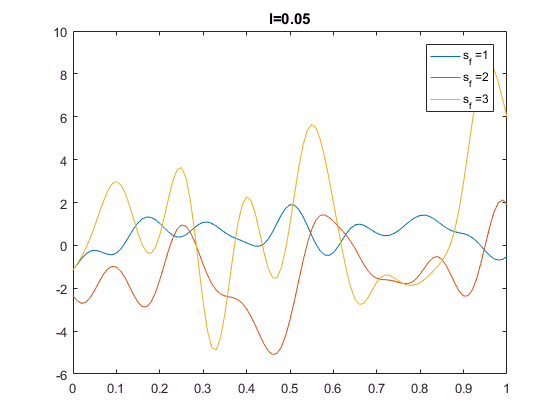

figure(2)
sf = zeros(3,1);
for i = 1:3
    ell2 = 0.05;
    sf(i) = i;
    
    hyp_cov = log([ell2,sf(i)]);
    gp_sample = gptp_sample(covfunc,x,hyp_cov);
    plot(x, gp_sample)
    hold on
end
title(['l=', num2str(ell2)])
legend(['s_f =', num2str(sf(1))], ['s_f =', num2str(sf(2))], ['s_f =', num2str(sf(3))])